# Lab - Optimization

**Topics: **fminbnd, fminsearch

clear, clc

## 1D Optimization

### Set up problem

As electric current moves through a wire heat generated by resistance is conducted through a layer of insulation and then convected to the surrounding air. The steady-state temperature of the wire can be computed as: $T=T_{\mathrm{air}} +\frac{q}{2\pi }\left\lbrack \frac{1}{k}\ln \left(\frac{r_w +r_i }{r_w }\right)+\frac{1}{h}\;\frac{1}{r_w +r_i }\right\rbrack$

Determine the thickness of insulation $r_i$(m) that minimizes the wire’s temperature given the following parameters: $q=75$ W/m, $r_w =6$mm, $k=0\ldotp 17$W/(m K), $h=12$W/(${\mathrm{m}}^2$ K), and $T_{\textrm{air}} =293$K.

q = 75;
r_w = .006;
k = .17;
h = 12;
T_air = 293;

f = @(r_i) T_air + (q/(2*pi))*((1/k)*log((r_w+r_i)/r_w)+(1/h)*(1./(r_w+r_i)));

### Plot to see what is reasonable

fplot(f, [r_w, 2*r_w], "b-.")
ylabel("WireTemperature [K]")
xlabel("Insulation Thickness [m]")

### Find the radius of the wire insulation that minimizes the wire temperature

[radMin, Tmin] = fminbnd(f, r_w, 2*r_w)

radMin = 0.0082

Tmin = 423.5398

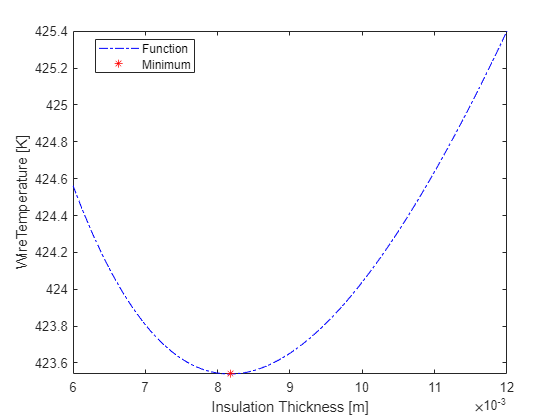

hold on
plot(radMin, Tmin, "r*")
hold off
legend("Function", "Minimum", "Location", "Best")

### What is the total thickness of the wire and insulation in mm to three decimals?

rTot = radMin + r_w;
fprintf("The total radius of the wire is %.3f mm", rTot*1000)

The total radius of the wire is 14.173 mm

## 2D Optimization

The head of a groundwater aquifer is described in Cartesian coordinates by: $h\left(x,y\right)=\frac{1}{1+x^2 +y^2 +x+\textrm{xy}}$

Find the head maximum between $-4\le x\le 2$ and $-2\le y\le 3$

### Set up the data

clc
clear

x = linspace(-4,2);
y = linspace(-2,3);

h = @(x,y) 1./(1 + x.^2 + y.^2 + x + x.*y);

[X,Y] = meshgrid(x,y);
Z = h(X,Y);

### Plot to see what's reasonable

surf(X,Y,Z)
xlabel("X position [m]")
ylabel("y position [m]")
zlabel("z position [m]")

### Find the maximum

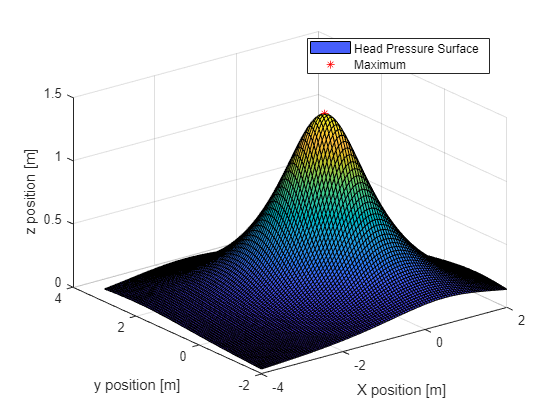

G = @(P) -h(P(1), P(2));
[Q, fmin] = fminsearch(G,[0,1]);
hold on
plot3(Q(1), Q(2), h(Q(1),Q(2)), "r*")
hold off
legend("Head Pressure Surface", "Maximum", "Location","best")